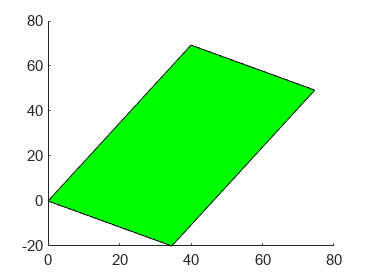

seta=30;
seta=(seta/180)*pi;
x=0;
y=0;
a=40;
b=80;

MyRect2(x,y,a,b,seta)

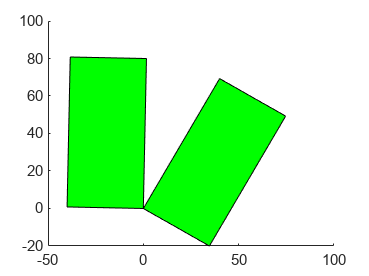

ans = 0

seta= 1.1800;
seta=(seta/180)*pi;
x=0;
y=0;
a=40;
b=80;

MyRect3(x,y,a,b,seta)

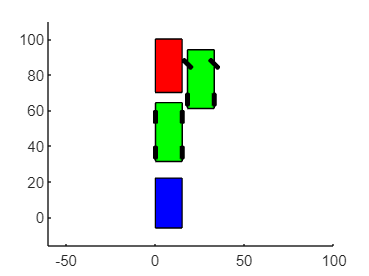

global wl;
global ww;
global D;
global L;
global WSeta; 
wl=7;
ww=2;
    A=15;
    L=20;
    D=5;
    F=8;
    B=L+D+F;
    PCC1x1=0;
    PCC1y1=-6;
    PCC1x2=0;
    PCC1y2=22;
    PCC1x3=15;
    PCC1y3=22;
    PCC1x4=15;
    PCC1y4=-6;
    PCC2x1=0;
    PCC2y1=70;
    PCC2x2=0;
    PCC2y2=100;
    PCC2x3=15;
    PCC2y3= 100;
    PCC2x4=15;
    PCC2y4=70;
    
%    tuning 1   
%     WSeta=65; 
%     WSeta=(WSeta/180)*pi; % degree to radians
%     S=8;
%     xi=PCC2x4+S;
%     yi=PCC2y4-12;
%     f1e=55;
%     
    
%     tuning  2    
%     WSeta=60; 
%     WSeta=(WSeta/180)*pi; % degree to radians
%     S=4;
%     xi=PCC2x4+S;
%     yi=PCC2y4-12;
%     f1e=46;
    
%     tuning  3
%     WSeta=40; 
%     WSeta=(WSeta/180)*pi; % degree to radians
%     S=.5;
%     xi=PCC2x4+S;
%     yi=PCC2y4-7;
%     f1e=33;
%     tuning  4
%     WSeta=45; 
%     WSeta=(WSeta/180)*pi; % degree to radians
%     S=.5;
%     xi=PCC2x4+S;
%     yi=PCC2y4-8.5;
%     f1e=35;
        
%     tuning  5 
    WSeta=45; 
    WSeta=(WSeta/180)*pi; % degree to radians
    S=3;
    xi=PCC2x4+S;
    yi=PCC2y4-9;
    f1e=38;
    
    axis([-60 100 -20 100],'equal');
    t=[0:0.01:pi];
    seta=2*t;
    Xc=xi-(L/tan(WSeta));
    Yc=yi+D;
    
    
    Rbl=sqrt(D^2+(L/tan(WSeta))^2);
    phi=atan(D/(L/tan(WSeta)));
            i=1;
            x=Xc+Rbl*cos(seta(i)+phi);
            y=Yc-Rbl*sin(seta(i)+phi);
            patch([PCC2x1 PCC2x2 PCC2x3 PCC2x4],[PCC2y1 PCC2y2 PCC2y3 PCC2y4],[1 0 0]);
            patch([PCC1x1 PCC1x2 PCC1x3 PCC1x4],[PCC1y1 PCC1y2 PCC1y3 PCC1y4],[0 0 1]);
            MyRect2(x,y,A,B,seta(i));

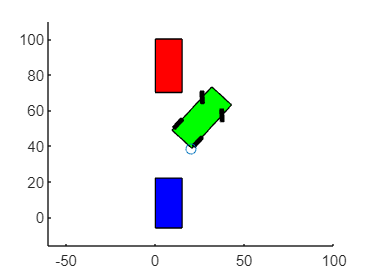

            pause(4);
    for i=2:f1e
            x=Xc+Rbl*cos(seta(i)+phi);
            y=Yc-Rbl*sin(seta(i)+phi);
            cla;
            patch([PCC2x1 PCC2x2 PCC2x3 PCC2x4],[PCC2y1 PCC2y2 PCC2y3 PCC2y4],[1 0 0]);
            patch([PCC1x1 PCC1x2 PCC1x3 PCC1x4],[PCC1y1 PCC1y2 PCC1y3 PCC1y4],[0 0 1]);
            MyRect2(x,y,A,B,seta(i));
            pause(.05);
    end
     xi=x+A*cos(seta(f1e));
     yi=y-A*sin(seta(f1e));
     hold on
%      plot(xi,yi,'o')

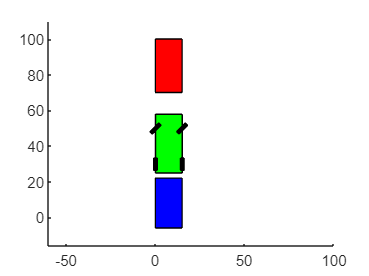

%     seta=-seta;
    Xc=xi+Rbl*cos(seta(f1e));
    Yc=yi-Rbl*sin(seta(f1e));
%     plot(Xc,Yc,'o')
    pause(1);
    
    for i=f1e:-1:1
            x=Xc-Rbl*cos(seta(i));
            y=Yc+Rbl*sin(seta(i));
            cla;
            patch([PCC2x1 PCC2x2 PCC2x3 PCC2x4],[PCC2y1 PCC2y2 PCC2y3 PCC2y4],[1 0 0]);
            patch([PCC1x1 PCC1x2 PCC1x3 PCC1x4],[PCC1y1 PCC1y2 PCC1y3 PCC1y4],[0 0 1]);
            [xa1 xb1 xb2 xa2 ya1 yb1 yb2 ya2]=MyRect3(x,y,A,B,seta(i));
            pause(.05);
    end

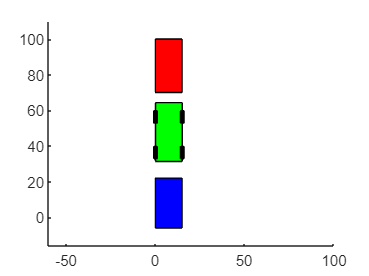

    
 pause(1);
 for i=1:13
 ya1=ya1+.5;
 yb1=yb1+.5;
 ya2=ya2+.5;
 yb2=yb2+.5;
 cla;
 patch([PCC2x1 PCC2x2 PCC2x3 PCC2x4],[PCC2y1 PCC2y2 PCC2y3 PCC2y4],[1 0 0]);
 patch([PCC1x1 PCC1x2 PCC1x3 PCC1x4],[PCC1y1 PCC1y2 PCC1y3 PCC1y4],[0 0 1]);           
 patch([xa1 xb1 xb2 xa2],[ya1 yb1 yb2 ya2],[0 1 0]);
 ya11=ya1+(D-wl/2);
 yb11=ya11+wl;
 ya21=ya2+(D-wl/2);
 yb21=ya21+wl;
 xa11=xa2+(ww/2);
 xb11=xa2+(ww/2);
 xa21=xa2-(ww/2);
 xb21=xa2-(ww/2);
 patch([xa11 xb11 xb21 xa21],[ya11 yb11 yb21 ya21],[0 0 0]);
 xa22=xa1-(ww/2);
 xb22=xa1-(ww/2);
 xa12=xa1+(ww/2);
 xb12=xa1+(ww/2);
 patch([xa12 xb12 xb22 xa22],[ya11 yb11 yb21 ya21],[0 0 0]);
 ya13=ya11+L;
 yb13=yb11+L;
 patch([xa11 xb11 xb21 xa21],[ya13 yb13 yb13 ya13],[0 0 0]);
 patch([xa12 xb12 xb22 xa22],[ya13 yb13 yb13 ya13],[0 0 0]);
 
 pause(.02);
 end